clc; format shortEng
% Materials
E = [77e9 73.6e9];
o_adm = [210e6 250e6];

Material_select = 2;
E_ = E(Material_select); o_adm_ = o_adm(Material_select);

m = 6;
g = 9.81;

%Thickness
b = 30e-3;


% Pivots
r = 0.008

r =      8.0000e-003


e = 0.00005

e =     50.0000e-006


k_piv =  2 * E_ * b * e^(2.5) / (9*pi*r^(0.5))

k_piv =     30.8686e-003


adm_piv = rad2deg(3*pi*o_adm_*sqrt(r)/(4*E_*sqrt(e)))

adm_piv =      5.8004e+000


% Compensation de poids
%Lames
num_lames = 1;
springs_in_series = 4;
springs_in_parallel = 1;
L = 0.14

L =    140.0000e-003


ratio = 60;
h = L/ratio

h =      2.3333e-003


% ratio = L/h

rig_lame = (num_lames * E_ * b * h^3) / (L^3);
adm_lame = springs_in_series*(o_adm_ * L^2) /(3 * E_ * h)

adm_lame =     38.0435e-003


k_p = rig_lame/(springs_in_series) * springs_in_parallel

k_p =      2.5556e+003



precharge_dist_p = m*g/k_p

precharge_dist_p =     23.0322e-003


precharge_check_p = (precharge_dist_p >= 15e-3)&&(adm_lame >= precharge_dist_p + 15e-3)

precharge_check_p = logical
   1


precharge_force_p = k_p * precharge_dist_p;



% Compensation de Rigidity avec Table a lames
syms k_r z
L1 = 250e-3;
L2 = 75e-3;
Lr2 = 0.1;
Lr3 = 19.1e-3;
lambda = (3*z^2)/(5*Lr2);
alpha = asin(z/L1);
beta = asin((2*L1*(1-cos(alpha)))/L2);
gamma1 = alpha+beta;
gamma2 = alpha-beta;
phi = asin(lambda/Lr3);

%Table a lames
num_lames = 2;
springs_in_series = 1;
springs_in_parallel = 1;
h = 0.000704

h =    704.0000e-006


ratio = Lr2/h %#ok<NASGU> 

ratio =    142.0455e+000



rig_lame = (num_lames * E_ * b * h^3) / (Lr2^3);
adm_lame = springs_in_series*(o_adm_ * Lr2^2) /(3 * E_ * h)

adm_lame =     16.0830e-003


k_r_table = rig_lame/(springs_in_series) * springs_in_parallel

k_r_table =      1.5408e+003


charge_crit = (8*pi^2 * E_ * b * h^3)/(12*Lr2^2)

charge_crit =    506.9038e+000



precharge_dist_r = 0.1;
L_r_rest = 0.06;
spring_length_ext = precharge_dist_r + L_r_rest

spring_length_ext =    160.0000e-003


res_var = sqrt(z^2 + (precharge_dist_r + L_r_rest - lambda)^2)-L_r_rest;

ener_a = 0.5 * k_piv * alpha.^2;
ener_b = 0.5 * k_piv * beta.^2;
ener_g1 = 0.5 * k_piv * gamma1.^2;
ener_g2 = 0.5 * k_piv *gamma2.^2;
ener_poids = 0.5 * k_p * (z+precharge_dist_p).^2;
ener_r_table = 0.5 * k_r_table *z^2;
ener_r_col = 0.5 * k_piv * phi^2;
ener_r_res = 0.5 * k_r * res_var^2;
ener_masse = -m*g*z;
E_tot = 4*(ener_a + ener_r_col) + 2*(ener_b + ener_g1 + ener_g2 + ener_r_table + ener_r_res) + ener_poids + ener_masse;

Force = diff(E_tot);

z = -15e-3:1e-4:15e-3;
k_r = 4975;
spring_precharge_force = k_r*precharge_dist_r

spring_precharge_force =    497.5000e+000


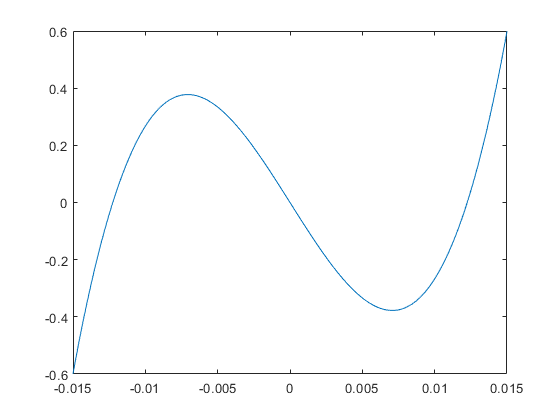


Force_num = eval(Force);
plot(z, Force_num)

maxForce = max(Force_num)

maxForce =    599.2573e-003


% Ressort dimensioning in function of k
syms h L
assume(h > 100e-6);
assume(L < 200e-3 );%& L <60*h );
num_lames = 1;
springs_in_series = 6;
springs_in_parallel = 1;

rig_form = k_r == (num_lames * E_ * b * h^3) / (L^3);
adm_form = precharge_dist_r/springs_in_series == (o_adm_ * L^2) /(3 * E_ * h);

sol = solve(rig_form, adm_form, [h L]);
h = eval(sol.h)

h =      2.5299e-003


L = eval(sol.L)

L =    192.9771e-003


ratio = L/h

ratio =     76.2785e+000
